% Impostazione del Workspace

clc
clear

Valori dei componenti R, L e C.

R = 10; % Resistenza [ohm]
L = 0.01; % Induttanza [H]
C = 1e-6; % Capacità [F]

Funzione di Trasferimento del circuito RLC.

num_l1 = [R*L 0];
den_l1 = [R*L*C L R];

% Funzione di trasferimento del circuito parallelo RLC.
H = tf(num_l1,den_l1)


H =
 
           0.1 s
  -----------------------
  1e-07 s^2 + 0.01 s + 10
 
Continuous-time transfer function.
Model Properties


Risposta in frequenza (Bode plot).

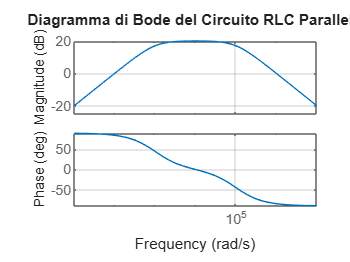

bode(H);
grid on;
title('Diagramma di Bode del Circuito RLC Parallelo');

Risposta al gradino.

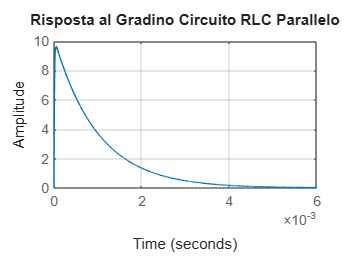

step(H);
grid on;
title('Risposta al Gradino Circuito RLC Parallelo');

Si individua in forma esplicita i poli della funzione di trasferimento (slide, pag. 1).

- Si nota che non sempre τ e μ sono reali, tutto dipende dai parametri R, L e C.

- Si analizza il determinante L - 4*R^2*C > 0:

- L1 > 5*(4*R^2*C): due soluzioni reali e distinte. Il sistema ha due poli reali negativi e quindi stabile.

- L2 = 4*R^2*C: due soluzioni reali e coincidenti. Il sistema ha due poli reali negativi e coincidenti e quindi stabile.

- L3 < 0.5*(4*R^2*C): due soluzioni complesse coniugate. Il sistema ha due poli complessi coniugati a parte reale negativa, quindi stabile che presenta però delle oscillazioni

NOTA: Per comprendere l’impatto sulla risposta a gradino dei differenti casi, separiamo l’analisi dell’effetto dei poli con quella dell’effetto degli zeri. Si ignora quindi lo zero nell’origine (si pone il numeratore pari a 1) (slide, pag 4).

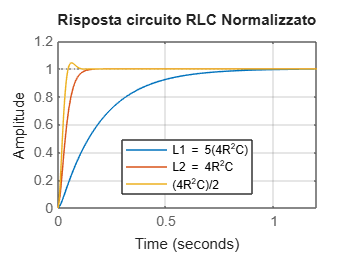

R = 100; % Resistenza [ohm]
C = 1e-4; % Capacità [F]
L1 = 5*(4*R^2*C); 
L2 = 4*R^2*C;
L3 = (4*R^2*C)/2;
L = [L1 L2 L3]; % Induttanza [H]

% FdT Normalizzata (si pone il numeratore pari a 1).
for i = 1:length(L) 
    num_l1 = 1;
    den_l1 = [C*L(i) L(i)/R 1];
    F = tf(num_l1,den_l1);
    step(F);
    hold on;
    grid on;
end

hold off;
title("Risposta circuito RLC Normalizzato");
legend("Location","best");
legend("L1 = 5(4R^2C)","L2 = 4R^2C", "(4R^2C)/2");

Si verifica la stabilità del sistema tramite luogo delle radici.

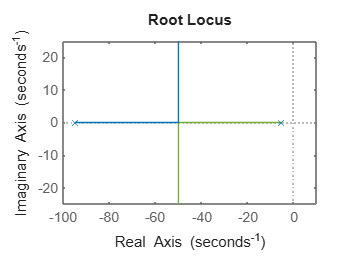

% FdT con L1
num = 1;
den = [C*L1 L1/R 1];
FL1 = tf(num,den);

% FdT con L2
num = 1;
den = [C*L2 L2/R 1];
FL2 = tf(num,den);

% FdT con L3
num = 1;
den = [C*L3 L3/R 1];
FL3 = tf(num,den);

rlocusplot(FL1)

pole(FL1)

ans =   -94.7214
   -5.2786


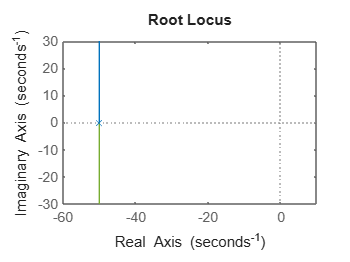


rlocusplot(FL2)

pole(FL2)

ans =   -50.0000
  -50.0000


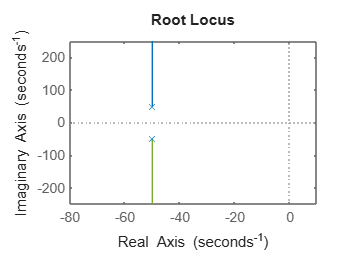


rlocusplot(FL3)

pole(FL3)

ans =  -50.0000 +50.0000i
 -50.0000 -50.0000i


Risposta del sistema non normalizzato (RLC puro).

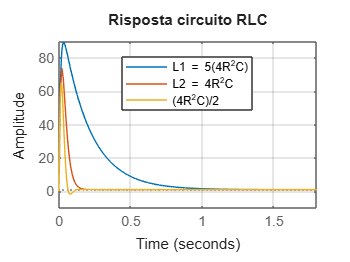

for i = 1:length(L) 
    num_l1 = [L(i) 1]; % Zero al numeratore.
    den_l1 = [C*L(i) L(i)/R 1];
    F = tf(num_l1,den_l1);
    step(F);
    hold on;
    grid on;
end

hold off;
title("Risposta circuito RLC");
legend("Location","best");
legend("L1 = 5(4R^2C)","L2 = 4R^2C", "(4R^2C)/2");